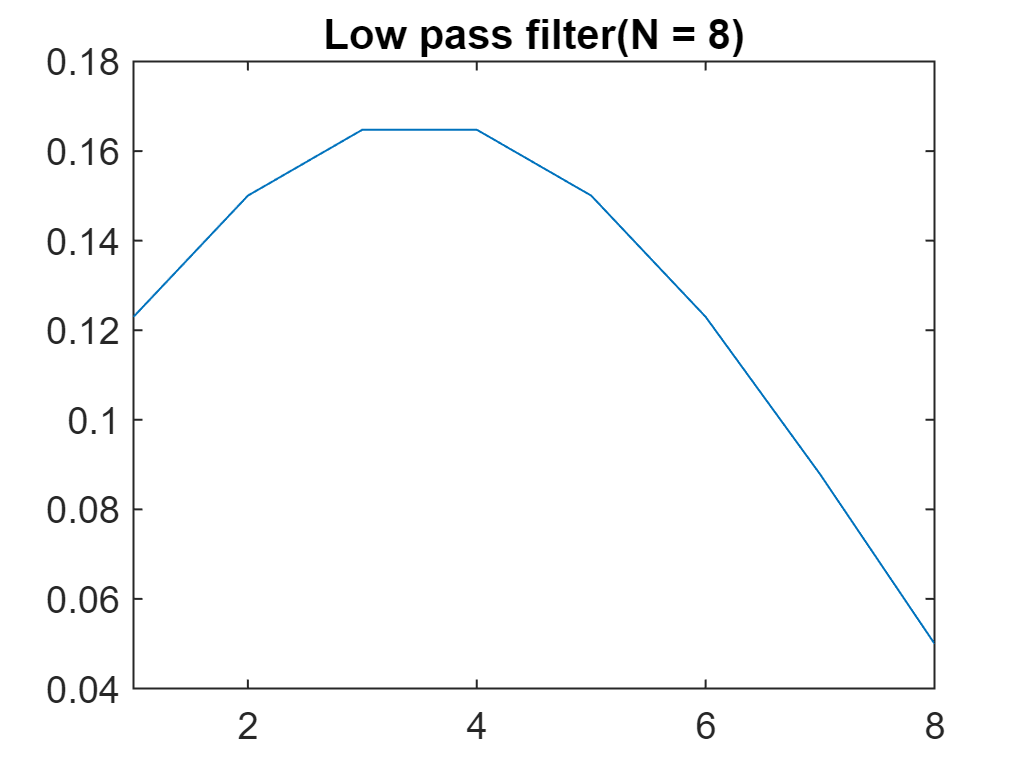

N = 8; %No. of samples
k = (N-1)/2; 
wc = pi/6; %cut-off frequency
n = 1 : 1: 10*N;
hd = zeros(1,N); %define filter dimension
w1 = zeros(1,N); %define window dimension
w2 = zeros(1,N);
w3 = zeros(1,N);
w4 = zeros(1,N);
w5 = zeros(1,N);

%Low pass filter
for i=1:N;
    if i == k;
        hd(i) = wc/pi;
    else
        hd(i)=(sin(wc*(i-k))/(pi*(i-k)));
    end
end
plot(hd)
xlim([1 N])
title('Low pass filter(N = 8)')

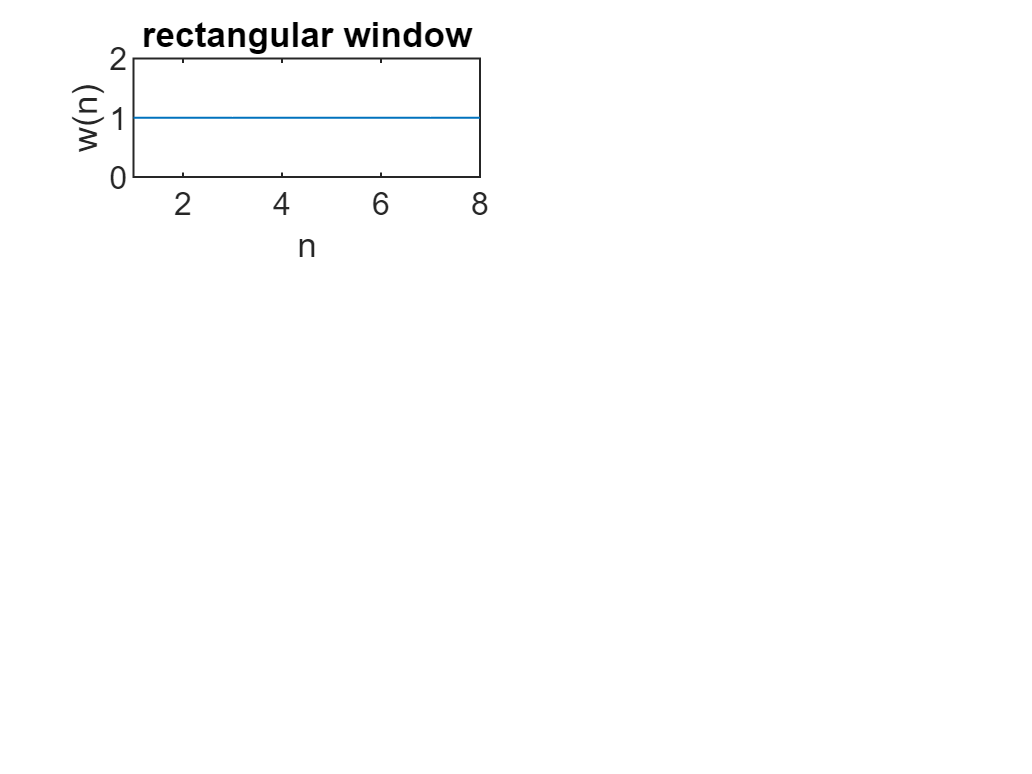


% rectangular window
for i=1:N
    w1(i)=1;
end
figure(1);
subplot(3,2,1);
plot(w1);
xlabel('n')
ylabel('w(n)')
xlim([1 N])
title('rectangular window')

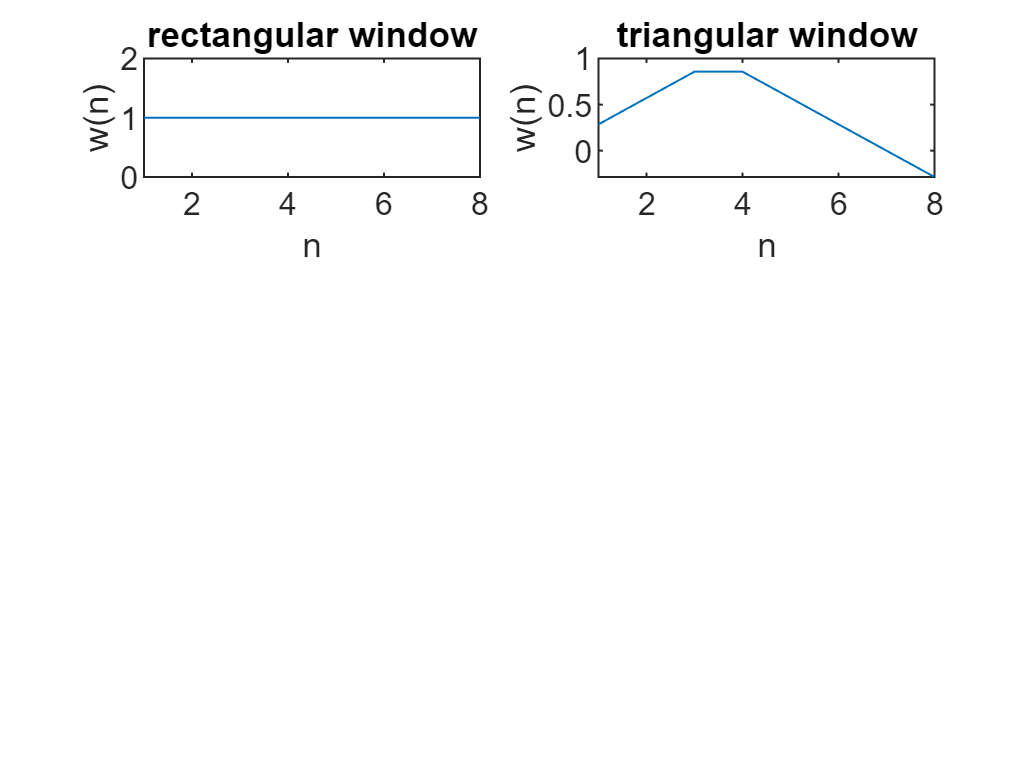


% triangular window
for i=1:N
    w2(i)=1-abs(2*((i-(N-1)/2)/(N-1)));
end
subplot(3,2,2);
plot(w2);
xlabel('n')
ylabel('w(n)')
xlim([1 N])
title('triangular window')

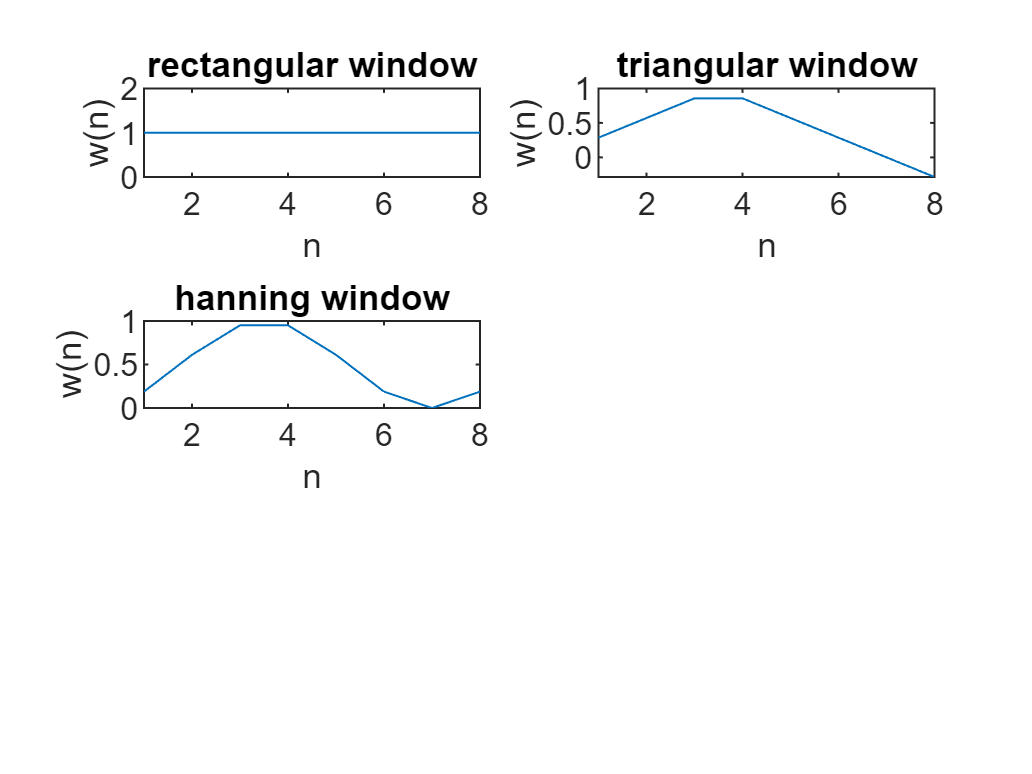


% hanning window
for i=1:N
    w3(i)=0.5-0.5*cos((2*pi*i)/(N-1));
end
subplot(3,2,3);
plot(w3);
xlabel('n')
ylabel('w(n)')
xlim([1 N])
title('hanning window')

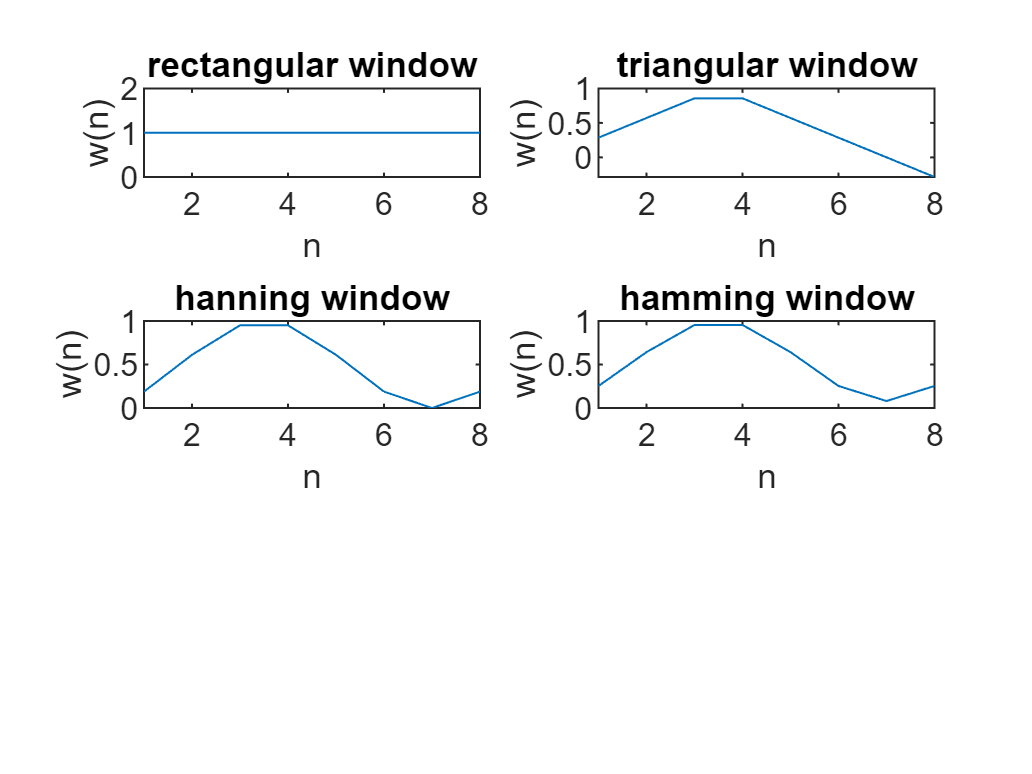


% hamming window
for i=1:N
    w4(i)=0.54-0.46*cos((2*pi*i)/(N-1));
end
subplot(3,2,4);
plot(w4);
xlabel('n')
ylabel('w(n)')
xlim([1 N])
title('hamming window')

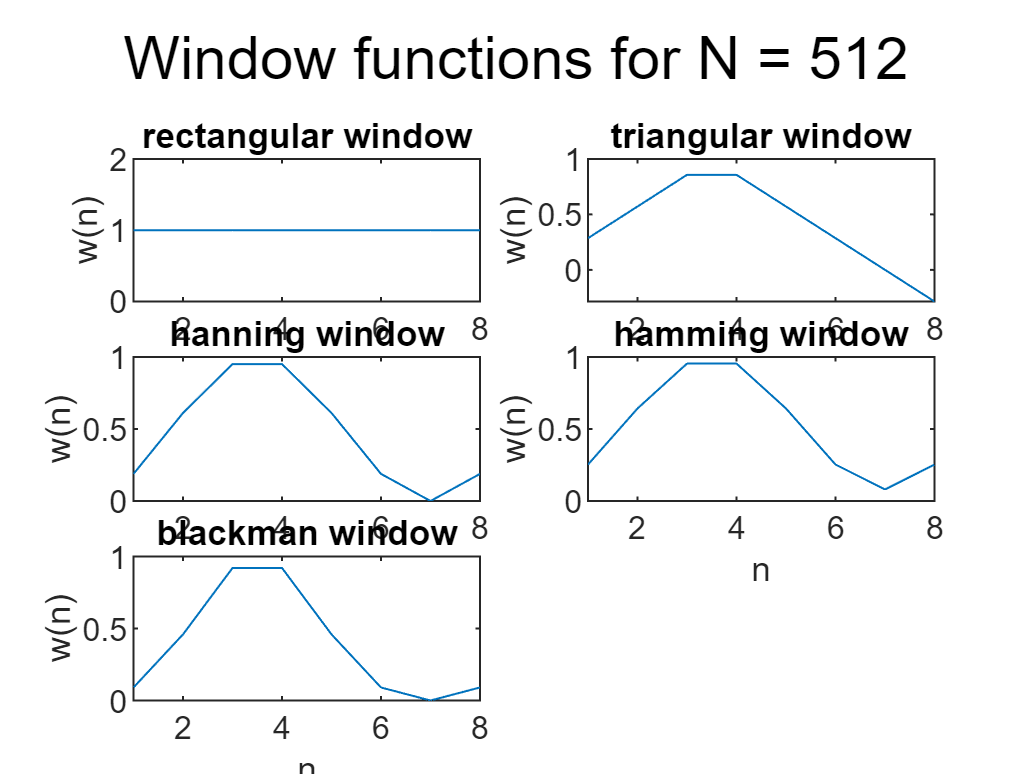


% blackman window
for i=1:N
    w5(i)=0.42-0.5*cos((2*pi*i)/(N-1)) +0.08*cos((4*pi*i)/(N-1));
end
subplot(3,2,5);
plot(w5)
xlabel('n')
ylabel('w(n)')
xlim([1 N])
title('blackman window')

sgtitle('Window functions for N = 512')

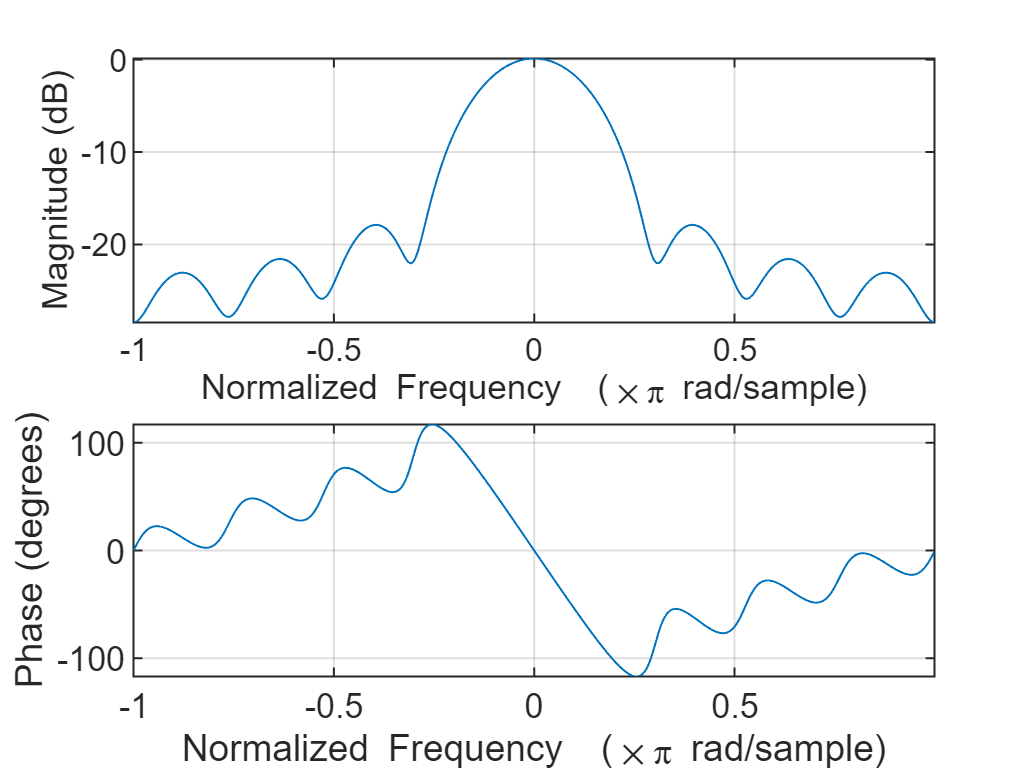


% Multiplication
figure(2);
f =-pi:0.01:pi;
w = w1; %choosing rectangular window function
h = hd.*w;
freqz(h,1,f);

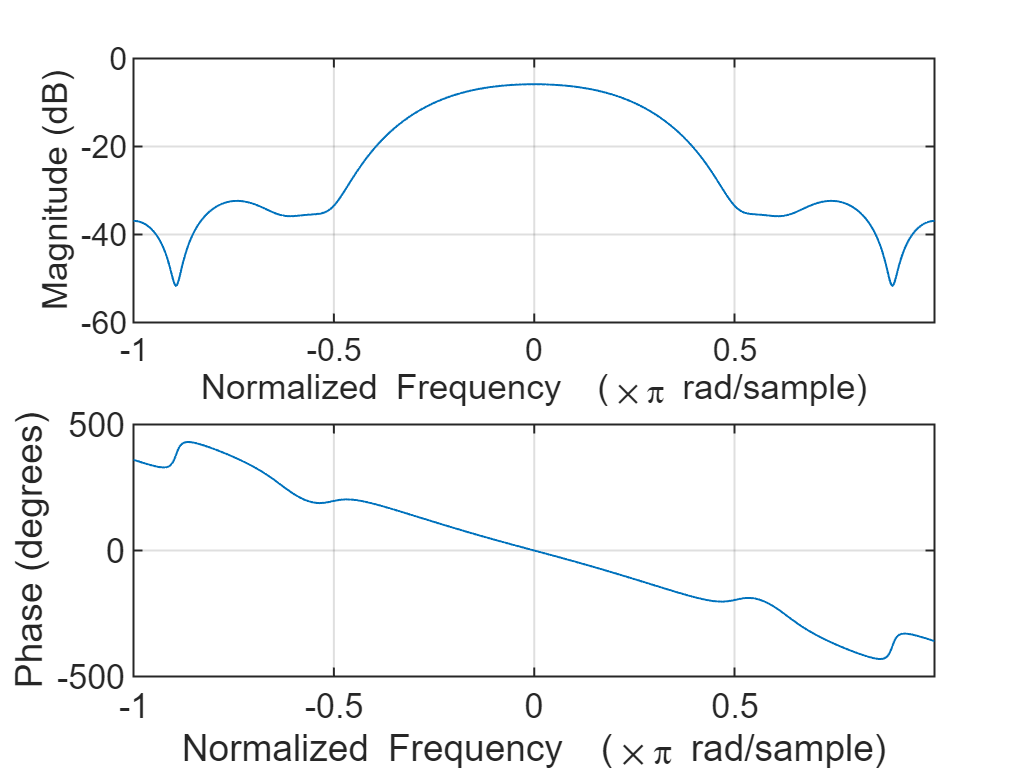


w = w2; %choosing triangular window function
h = hd.*w;
freqz(h,1,f);

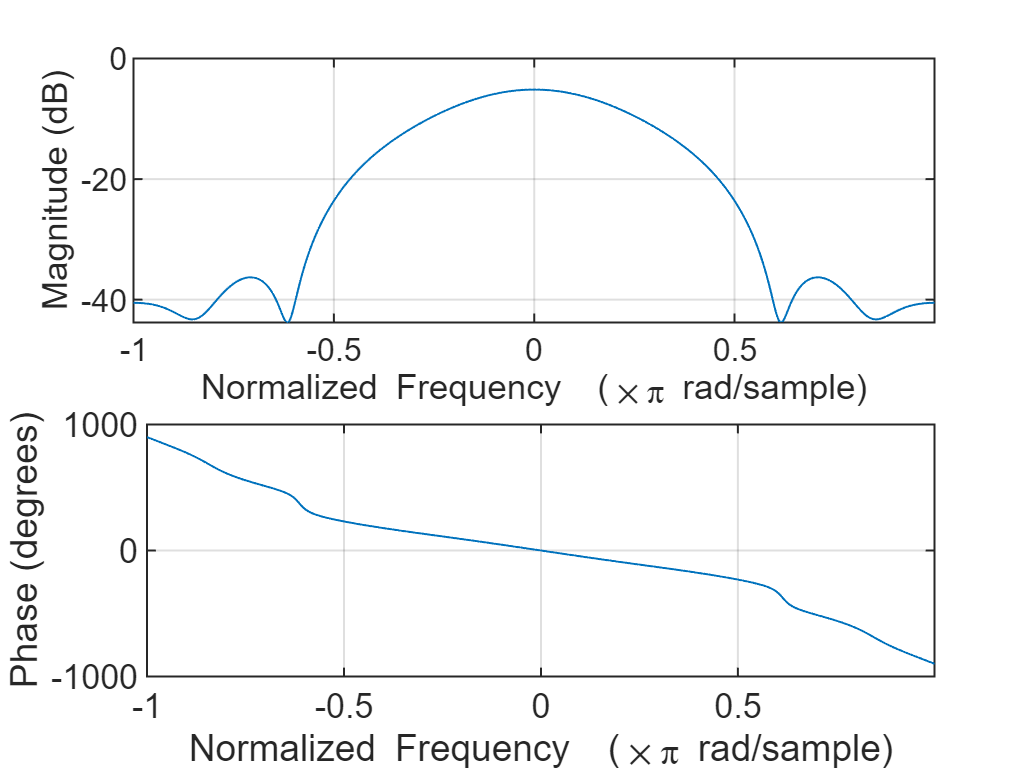


w = w3; %choosing hamming window function
h = hd.*w;
freqz(h,1,f);

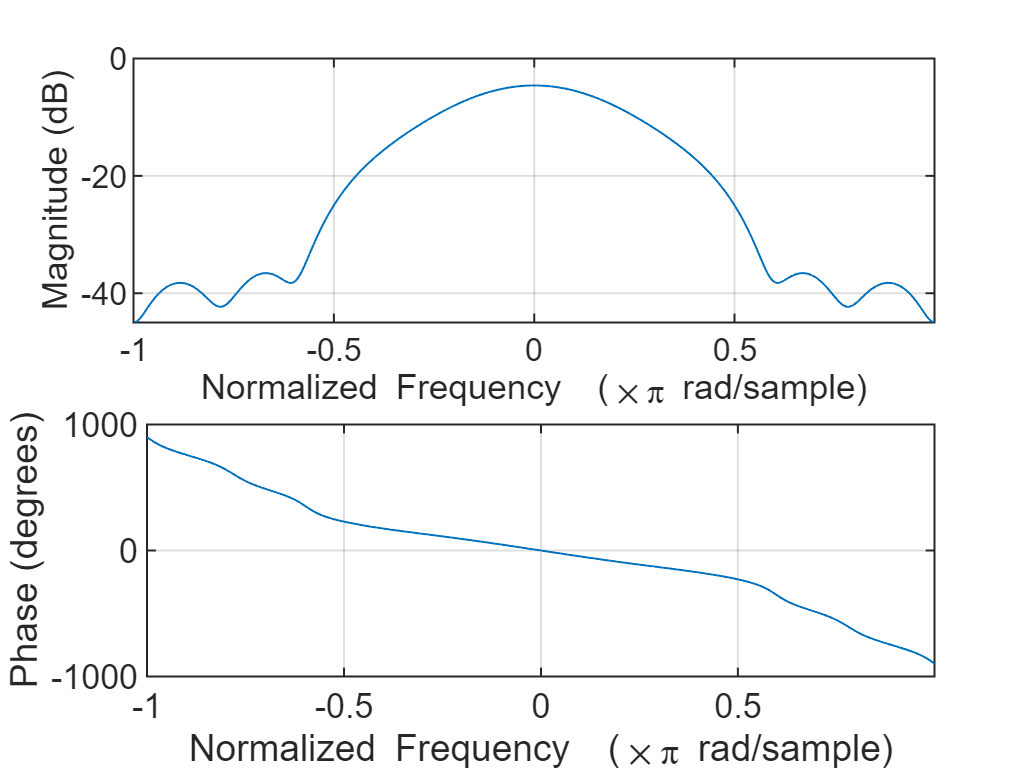


w = w4; %choosing hanning window function
h = hd.*w;
freqz(h,1,f);

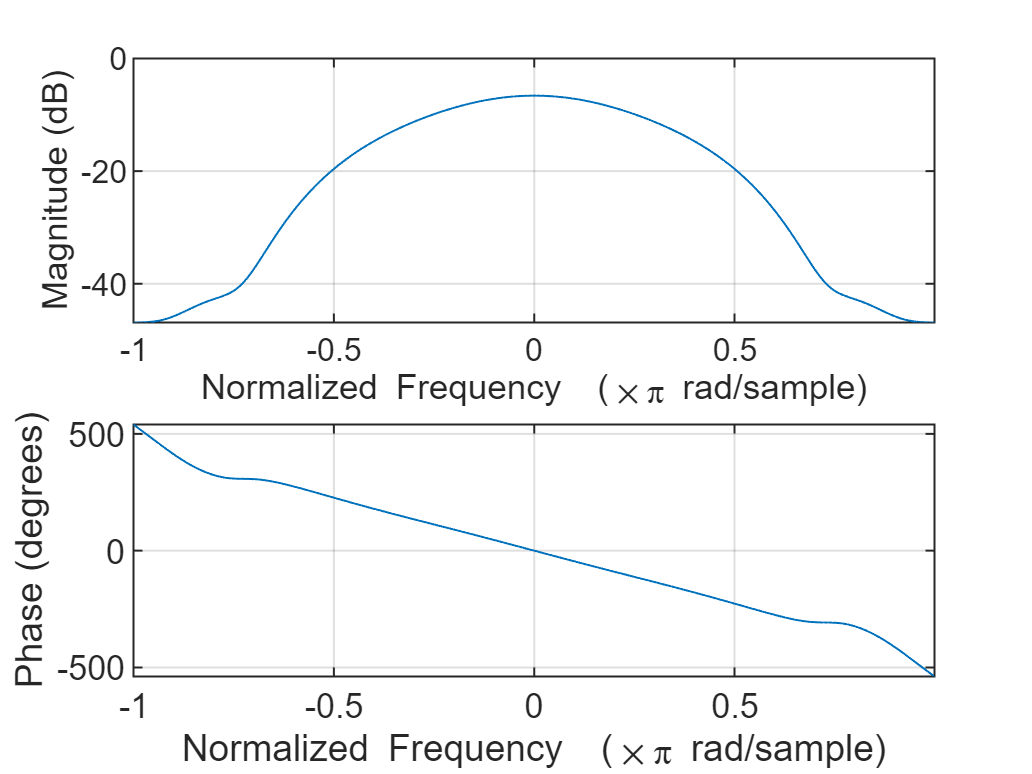


w = w5; %choosing blackman window function
h = hd.*w;
freqz(h,1,f);

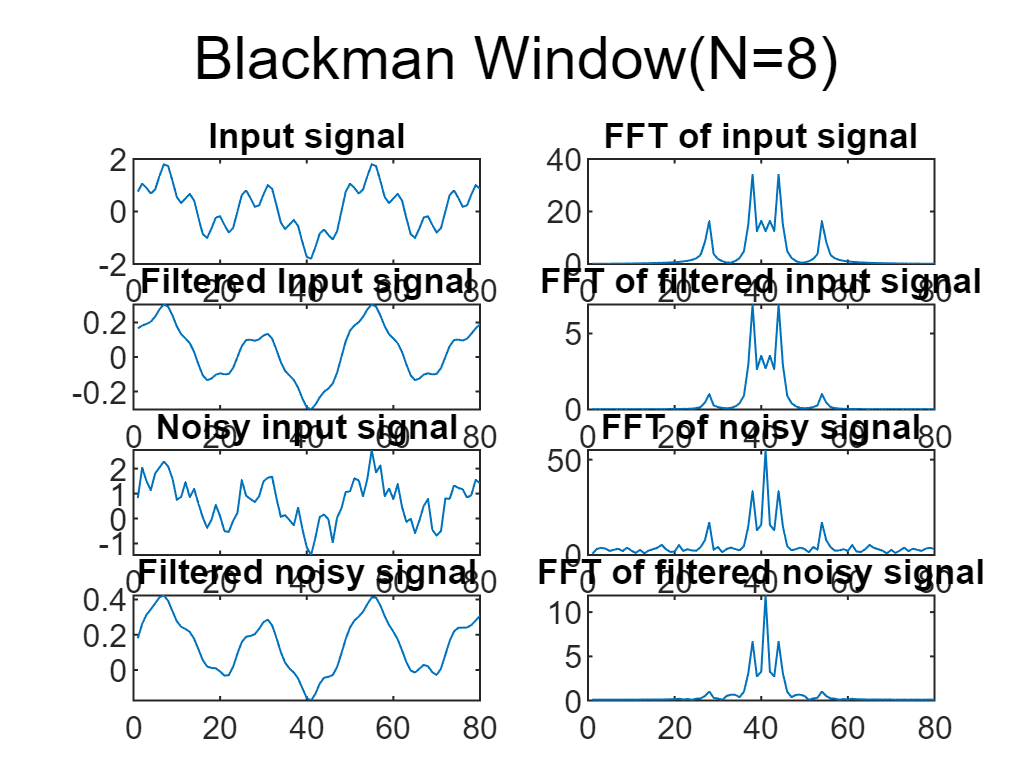

w = w1;
figure;
x = sin((wc/2)*n) + 0.5*sin((wc/4)*n) + 0.5*sin(2*wc*n);%input signal
subplot(4,2,1);
plot(n,x)
title('Input signal')
xlim([0 80]);
X = fft(x); %fft of input signal
X = fftshift(X);
subplot(4,2,2);
plot(abs(X))
title('FFT of input signal')

y = filtfilt(h,1, x); %Filtering input signal
subplot(4,2,3);
plot(y)
xlim([0 80])
title('Filtered Input signal')

Y = fft(y); %FFT of filtered signal
Y = fftshift(Y);
subplot(4,2,4);
plot(abs(Y))
title('FFT of filtered input signal')

noise = rand(size(n)); %noise signal
x = x +noise; %adding noise to input signal
subplot(4,2,5);
plot(n,x)
title('Noisy input signal')
xlim([0 80]);

X = fft(x); %fft of noisy signal
X = fftshift(X);
subplot(4,2,6);
plot(abs(X))
title('FFT of noisy signal')

y = filtfilt(h,1,x);%filtering noisy signal
subplot(4,2,7);
plot(y)
xlim([0 80])
title('Filtered noisy signal')

Y = fft(y); %FFT of filtered noisy signal
Y = fftshift(Y);
subplot(4,2,8);
plot(abs(Y))
title('FFT of filtered noisy signal')
sgtitle("Blackman Window(N=8)")

signal_amp = max(abs(y))

signal_amp = 0.4225

noise_amp = max(abs(noise))

noise_amp = 0.9904

r = snr(x,noise)

r = 5.2140